# Convergencia Newton-Raphson

syms x
f(x)=x^3-3*x+2

$$f(x) = x^{3}-3\,x+2$$

x0=-3; %Estimación incial
e=1*10^-8 %Tolerancia

e = 1.0000e-08

format long
[sol,En,matrizEn,n,sol_parcial]=convergencia_newtonRaphson(f,x0,e,-2)

Método de Newton-Raphson

Raiz= -2.000000 hallado en 6 iteraciones.

$$sol(x) = -\frac{165193494957282506521987}{82596747478641253260993}$$

En =    1.000000000000000   0.333333333333333   0.055555555555556   0.001949317738791   0.000002528297975   0.000000000004262   0.000000000000000


matrizEn = 	1.0e+11 *

   0.000000000003333   0.000000000003333   0.000000000003333
   0.000000000001667   0.000000000005000   0.000000000015000
   0.000000000000351   0.000000000006316   0.000000000113684
   0.000000000000013   0.000000000006654   0.000000003413346
   0.000000000000000   0.000000000006667   0.000002636813333
   0.000000000000000   0.000000000006667   1.564388390513333


n =      6


sol_parcial =   -2.333333333333333  -2.055555555555555  -2.001949317738791  -2.000002528297975  -2.000000000004261  -2.000000000000000


sol1=vpa(sol) %Simplificar la solución simbólica comando vpa.

$$sol1(x) = -2.0000000000000000000000121070143$$

En1=vpa(En)

$$En1 = \left(\begin{array}{ccccccc} 1.0 & 0.33333333333333333333333333333333 & 0.055555555555555555555555555555556 & 0.0019493177387914230019493177387914 & 0.0000025282979750861516823651382879223 & 0.0000000000042615163261667250261314426090164 & 0.000000000000000000000012107014265405435041815718415279 \end{array}\right)$$

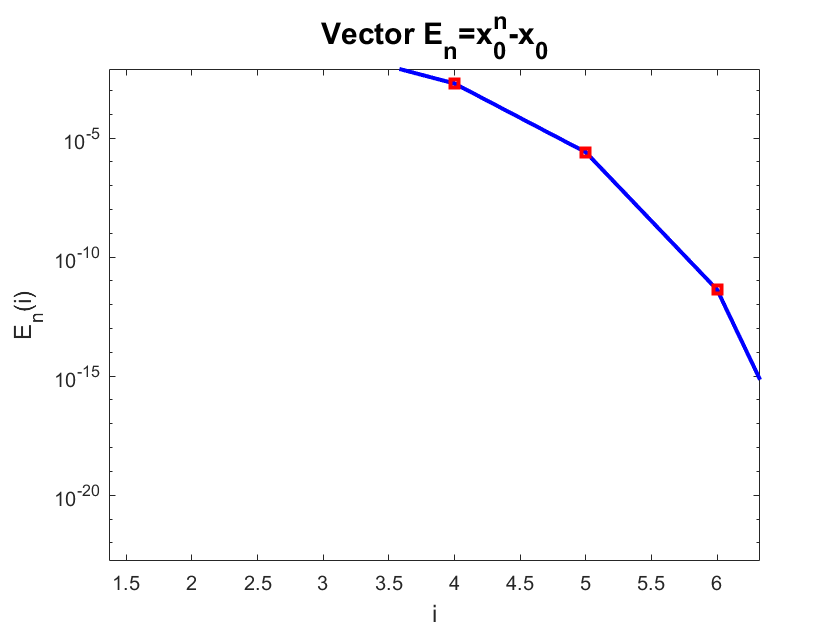

%Representación vector En
semilogy(En1,'-bs','LineWidth',2,'MarkerEdgeColor','r','MarkerSize',5)
hold on
title('Vector E_n=x_0^n-x_0','FontSize',15)
xlabel('i',"FontSize",12)
ylabel('E_n(i)','FontSize',12)
hold off

%--------------------------------------------------

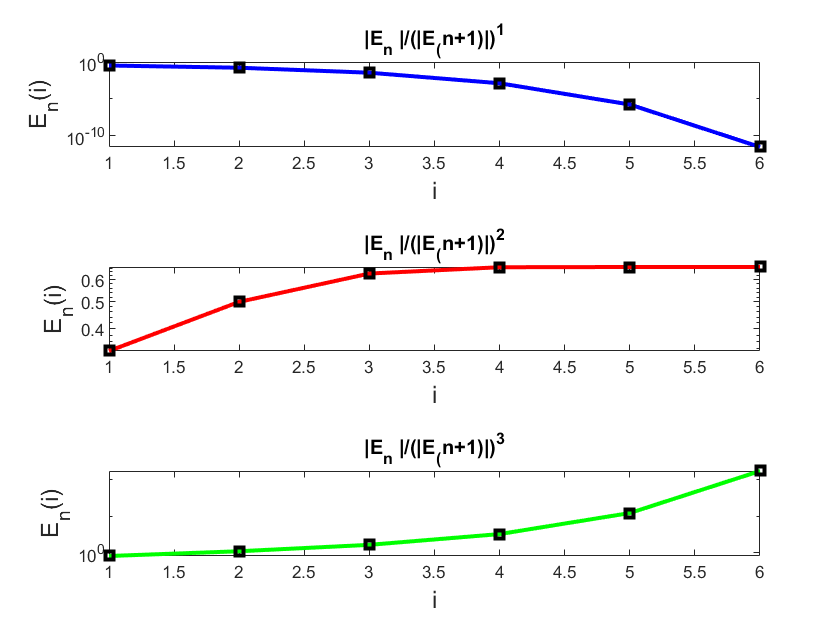

%Representación valor E_n/E_n+1 para k=1,2,3
t = tiledlayout(3,1);
nexttile
semilogy(matrizEn(:,1),'-bs','LineWidth',2,'MarkerEdgeColor','k','MarkerSize',5)
xlabel('i',"FontSize",12)
ylabel('E_n(i)','FontSize',12)
title('|E_n |/(|E_(n+1)|)^1','FontSize',10)
nexttile
semilogy(matrizEn(:,2),'-rs','LineWidth',2,'MarkerEdgeColor','k','MarkerSize',5)
xlabel('i',"FontSize",12)
ylabel('E_n(i)','FontSize',12)
title('|E_n |/(|E_(n+1)|)^2','FontSize',10)
nexttile
semilogy(matrizEn(:,3),'-gs','LineWidth',2,'MarkerEdgeColor','k','MarkerSize',5)
xlabel('i',"FontSize",12)
ylabel('E_n(i)','FontSize',12)
title('|E_n |/(|E_(n+1)|)^3','FontSize',10)

Constante K de convergencia:

df2=diff(f,2);
df=diff(f);
K=vpa(abs(1/2*(subs(df2,x,2)/subs(df,x,2))))

$$K(x) = 0.66666666666666666666666666666667$$

%Representación gráfica de la función, raíz y estimación incial.
fplot(f,[-5,5],'Color','b','LineWidth',2)
fplot(f,[-5,5],'Color','b','LineWidth',2)
hold on
grid on
plot(-3,0,'.g','MarkerSize',20)
plot(-2,0,'.r','MarkerSize',20)
yline(0)
title('Función f(x)','FontSize',12)
legend({'f(x)=x^3-3x+2','Estimación inicial','Raiz'},'Location','northwest')
xlabel('X')
ylabel('Y')
hold off
%------------------------------------------------
